# Control de sistemas biológicos TP N°1

A continuación se resuelve el problema 1 de la práctica N°1.

El modelo a controlar es el siguiente:

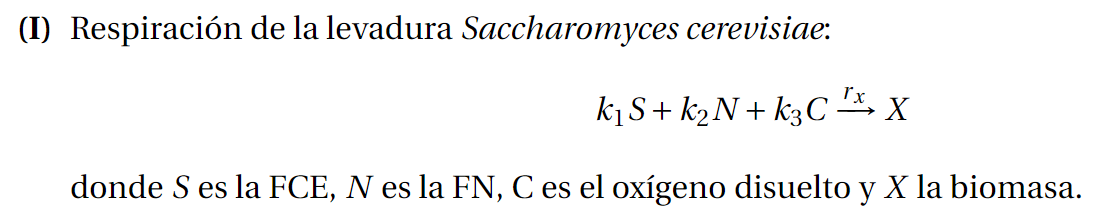

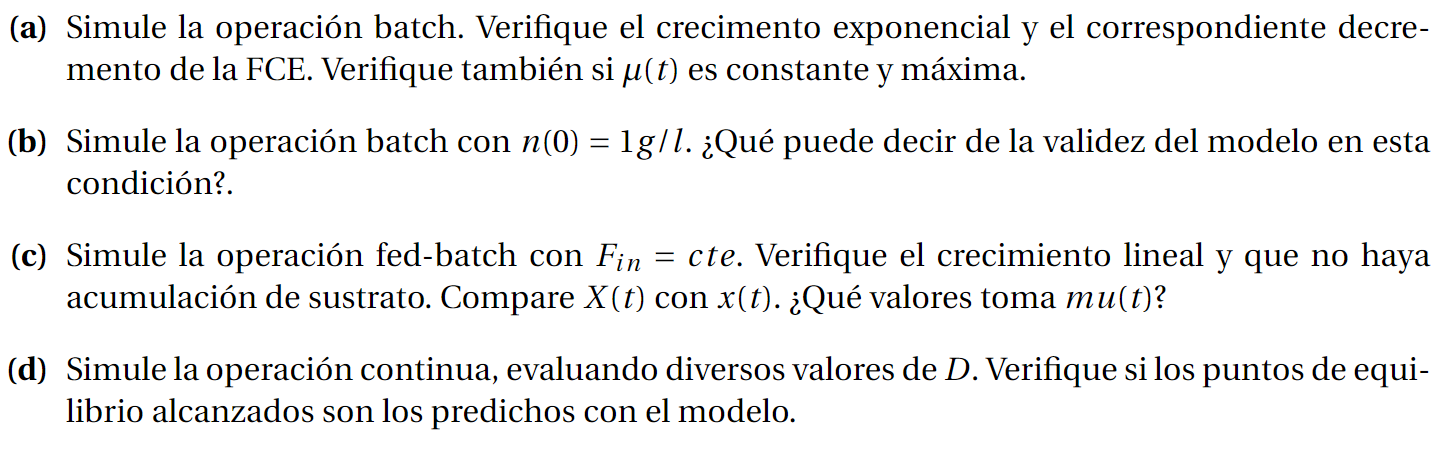

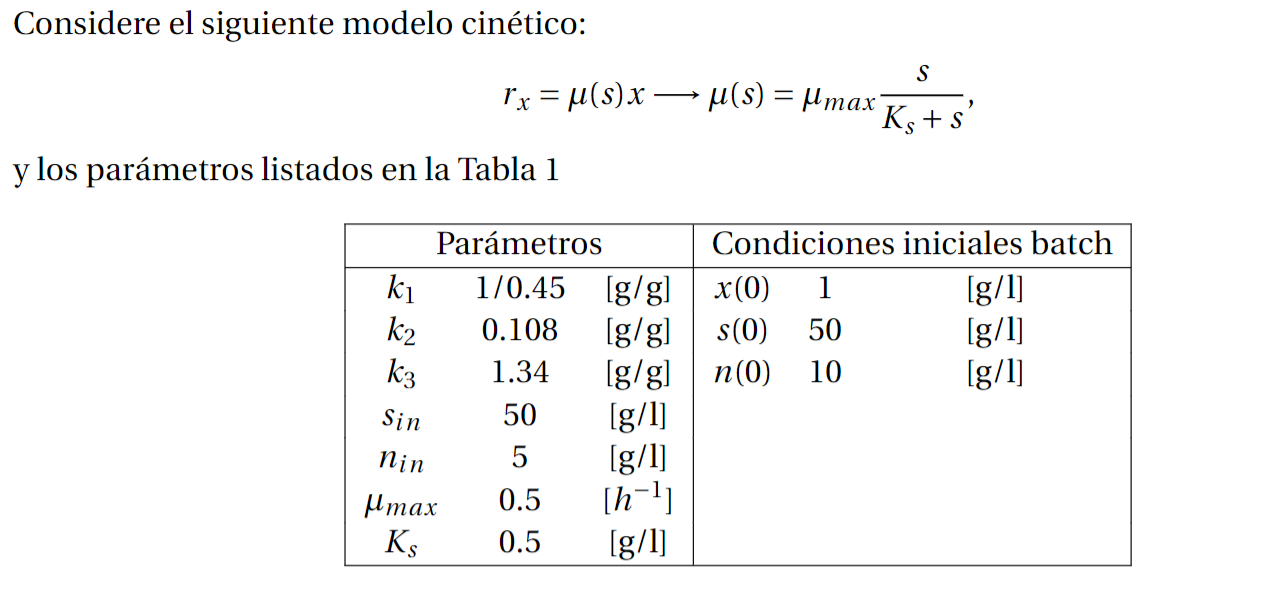

clc; clear all;

Defino los parámetros del modelo para un batch con modelo de Monod

% Definimos parámetros del modelo
mumax=0.5;
Ks=0.5;
K=[1;-0.4];

% Creamos una estructura para pasar los parámetros al bloque función u
% otros bloques
parametrosModelo.mumax=mumax;
parametrosModelo.Ks=Ks;
parametrosModelo.K=K;

% Definimos entradas y condiciones iniciales
xi_in=[0;10];
D=0.1;
xi0=[1;1];

sim_out = sim('TP1\basicModelWithMonod.slx')

sim_out =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [51x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Grafico los resultados de la simulación

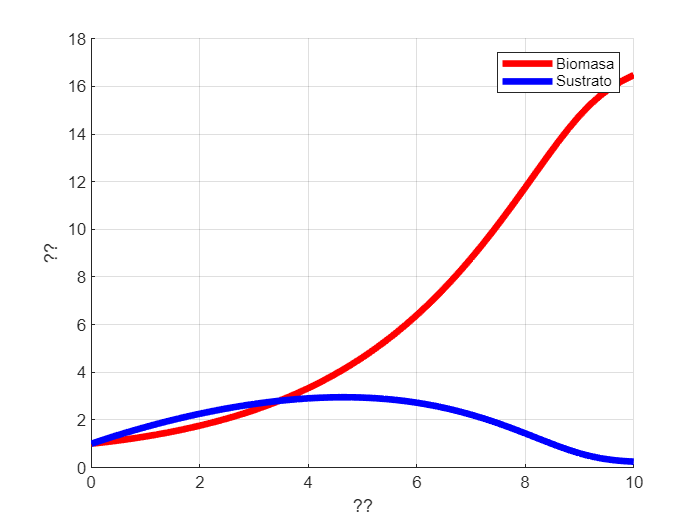

time = sim_out.simout.Time;
biomass = reshape(sim_out.simout.Data(1,1,:), size(time));
sustrate = reshape(sim_out.simout.Data(2,1,:), size(time));

fig = figure();
hold on; grid on;
xlabel('??');
ylabel('??');

plot(time, biomass, 'r', 'LineWidth', 4);
plot(time, sustrate, 'b', 'LineWidth', 4);

legend('Biomasa', 'Sustrato');